# CharFunTool User Guide

# The Characteristic Fuctions Toolbox for MATLAB

**1st Edition (21-Oct-2018)**

**CharFunTool version 1.4 (21-Oct-2018)**

**Edited by: Viktor Witkovsky **

**CharfunTool was created in January 2017 by: **

**Viktor Witkovsky**

**and is continuously developing with help of the (still growing) CharFunTool Development Team**

**Current members: **

**Viktor Witkovsky, Gejza Wimmer, Tomas Duby, Andrej Gajdoš, Jozef Hanč**

Former members: Ľudmila Šimková

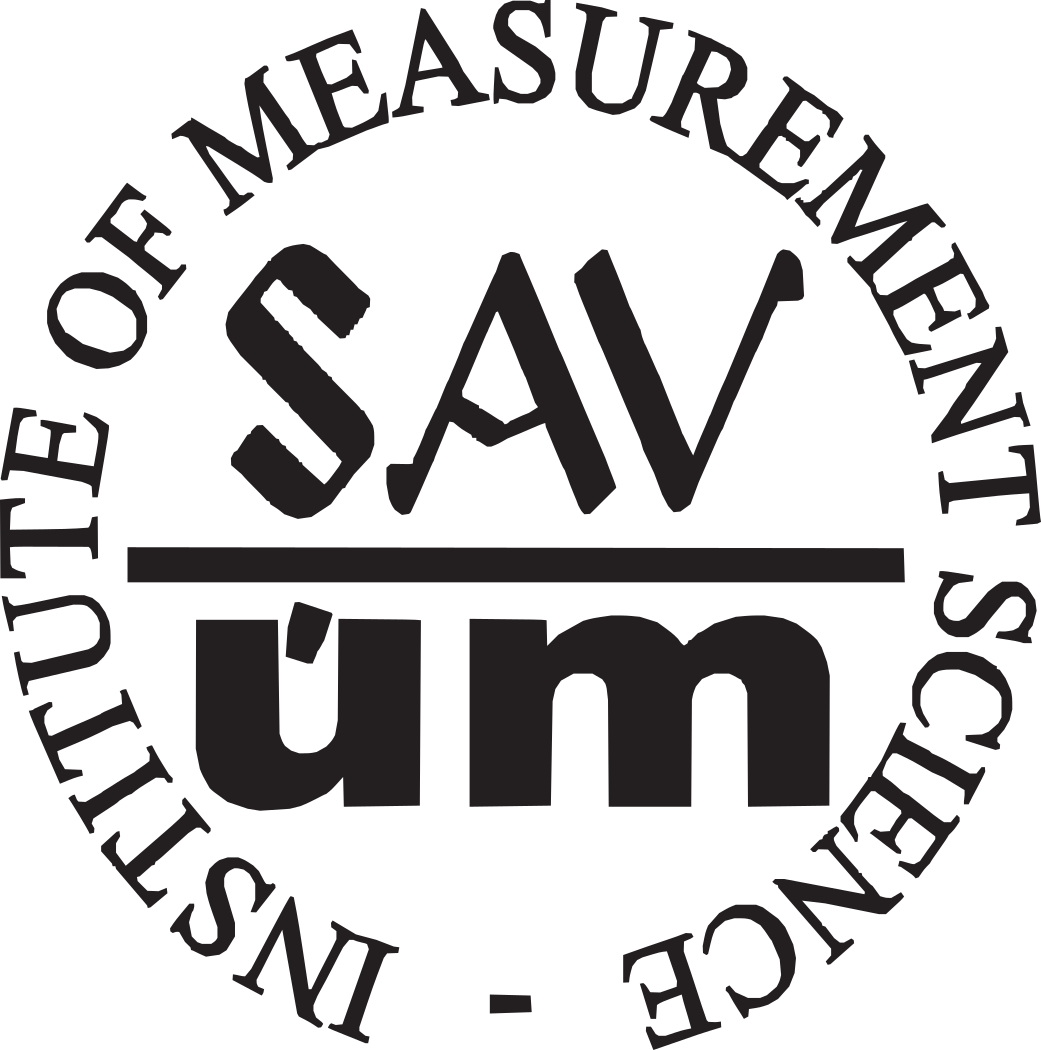

Copyright 2018 by Viktor Witkovsky and the Institute of Measurement Science of the Slovak Academy of Sciences, Bratislava, Slovakia. All rights reserved.

For more information, write to witkovsky@gmail.com.

MATLAB is a registered trademark of The MathWorks, Inc. For MATLAB product information, please write to info@mathworks.com.

## Preface

This guide is an introduction to the use of CharFunTool, an open source software package that aims to provide repository of algorithms for computing the characteristic functions and tools for their combinations and numerical inversion.

Application of the exact statistical inference frequently leads to a non-standard probability distributions of the considered estimators or test statistics. Frequently, evaluation of the probability density function (PDF), cumulative distribution function (CDF), and/or the quantile function (QF) is possible from the characteristic function (CF). 

In many important situations, derivation of the CFs is more simple than derivation of the PDFs and/or CDFs. In particular, the exact distribution of many estimators and test statistics can be structurally expressed as a linear combination or product of independent random variables with known distributions and characteristic functions as is the case for many standard multivariate test criteria. However, analytical inversion of the characteristic function (if possible) frequently leads to complicated expressions of the corresponding distribution functions, CDF/PDF and the required quantiles. 

As we shall illustrate here, for many applications, the method based on simple implementation of the numerical inversion of the characteristic functions is fully sufficient.

I gratefully acknowledge the support of the Institute of Measurement Science of the Slovak Academy of Sciences in Bratislava, Slovakia, and also the support by the Slovak Research and Development Agency, and by the Scientific Grant Agency of the Ministry of Education of the Slovak Republic and the Slovak Academy of Sciences, projects APVV-15-0295, VEGA 2/0054/18, VEGA 2/0011/16. 

Most especially I acknowledge and praise my collaborators and especially the contributors to CharFunTool. For their efficient cooperation and development efforts, I thank especially to  Gejza Wimmer (Mathematical Institute  of the Slovak Academy of Science in Bratislava), Tomas Duby (OAA Computing, Oxfordshire, UK), Andrej Gajdoš and Jozef Hanč (Pavol Jozef Šafárik University in Košice), and Ľudmila Šimková (former student at the Comenius University in Bratislava). Further, for their support and discussions, I would like to thank my colleagues at the Institute of Measurement Science, František Rublík, Anna Krakovská, Martina Chvosteková, and Jozef Jakubík, as well as the project partners and collaborators, Stanislav Ďuriš, Rudolf Palenčár (Slovak University of Technology in Bratislava), Zuzana Ďurišová (Slovak Institute of Metrology).

Viktor Witkovsky

Bratislava, October 2018

## **CharFunTool:The Characteristic Functions Toolbox**

The Characteristic Functions Toolbox (CharFunTool) is a MATLAB repository of characteristic functions and tools for their combinations and numerical inversion.

CharFunTool consists of a set of algorithms for evaluating selected characteristic functions and algorithms for numerical inversion of the combined and/or compound characteristic functions, used to evaluate the cumulative distribution function (CDF), the probability density function (PDF), and/or the quantile function (QF).

## Instalation

To install, you can either clone the directory with Git or download a .zip file. 

- Option 1: Download .zip file

Download a .zip of CharFunTool from

## Inversion algorithms

The toolbox comprises different inversion algorithms, including those based on simple trapezoidal quadrature rule for computing the integrals defined by the Gil-Pelaez formulae, and/or based on using the FFT algorithm for computing the Fourier transform integrals.

### Algorithms for numerical inversion of the characteristic functions

#### cf2DistBV

#### cf2DistFFT

#### cf2DistGP

## Repository of the characteristic funtions

CharFunTool consists of a set of algorithms for evaluating selected characteristic functions and algorithms for numerical inversion of the combined and/or compound characteristic functions,

### Characteristic functions of general probability distributions

#### cf_ArcsineSymmetric

The function` cf_ArcsineSymmetric` evaluates the characteristic function of a linear combination (resp. convolution) of independent zero-mean symmetric ARCSINE distributed random variables, defined on the interval $(-1,1)$.

The characteristic function of  is defined by  


$$\mathop{\mathrm{cf}}(t) = \mathop{\mathrm{besselj}}(0,t)$$


where $\mathop{\mathrm{besselj}}(\nu,t)$ is the Bessel function of the first kind of order $\nu$. Hence, the characteristic function of a linear combination $Y=\sum_{i=1}^N c_i X_i$, where $c_i$ are real coefficients, is 


$$\mathop{\mathrm{cf}}_Y(t) = \prod_{i=1}^N \mathop{\mathrm{cf}}_{X_i}(c_i t)$$
 

where $X_i \sim \mathop{\mathrm{ArcsineSymmetric}}(-1,1)$ are independent random variables defined on $(-1,1)$ and $\mathop{\mathrm{cf}}_{X_i}(t)$ are the characteristic functions of $X_i$  for all $i = 1,\dots,N$.

Syntax:

where

- `t` is a vector or array of real values, where the CF is evaluated.

- `coef` is a vector of the coefficients of the linear combination of the symmetric arcsine distributed random variables. If `coef` is scalar, it is assumed that all coefficients are equal. If empty, default value is `coef = 1`.

For more details see [https://en.wikipedia.org/wiki/Arcsine_distribution](https://en.wikipedia.org/wiki/Arcsine_distribution).

**Example 1:*** Plot the characteristic function of the symmetric arcsine distribution on the interval *$(-1,1)$*.*

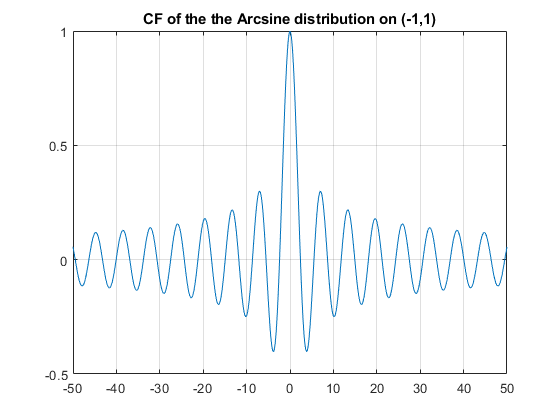

t    = linspace(-50,50,501);
cf   = cf_ArcsineSymmetric(t);
figure; plot(t,cf); grid
title('CF of the the Arcsine distribution on (-1,1)')

**Example 2:*** Plot the characteristic function of a linear combination of independent random variables with symmetric arcsine distribution on the interval *$(-1,1)$*.*

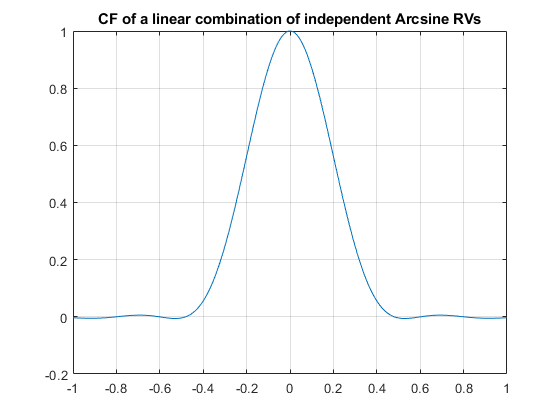

t    = linspace(-1,1,501);
coef = [1 2 3 4 5];
cf   = cf_ArcsineSymmetric(t,coef);
figure; plot(t,cf); grid
title('CF of a linear combination of independent Arcsine RVs')

**Example 3:*** Calculate and plot the PDF and CDF of a linear combination of independent random variables with symmetric arcsine distributions on the interval *$(-1,1)$* by using the inversion algorithm *`cf2DistGP`*.The structure *`result`* containts all the calculated information.*

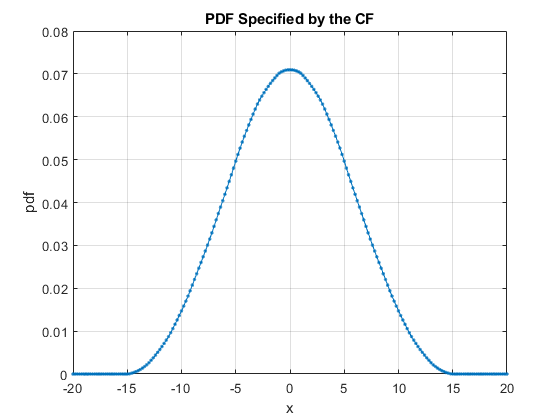

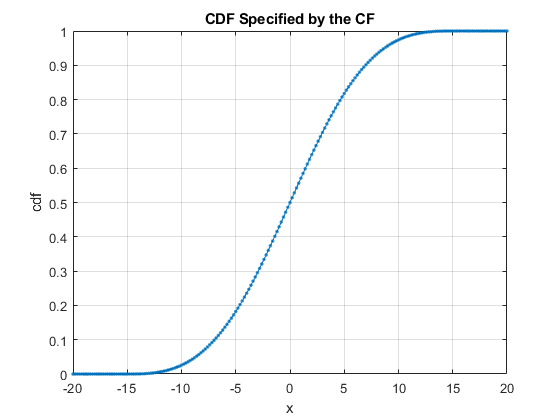

result = struct with fields:
            Description: 'CDF/PDF/QF from the characteristic function CF'
                      x: [1×201 double]
                    cdf: [1×201 double]
                    pdf: [1×201 double]
                   prob: [0.9000 0.9500 0.9900]
                     qf: [6.9485 8.6950 11.4134]
                     cf: @(t)cf_ArcsineSymmetric(t,coef)
             isCompound: 0
             isCircular: 0
               isInterp: 0
           SixSigmaRule: 6
                      N: 4096
                     dt: 0.0998
                      T: 408.9707
          PrecisionCrit: 2.7357e-13
        myPrecisionCrit: 1.0000e-12
          isPrecisionOK: 1
                  xMean: 0
                   xStd: 5.2440
                   xMin: -31.4643
                   xMax: 31.4643
                cfLimit: 0
              cdfAdjust: 0
    nNewtonRaphsonLoops: 8
           qfCorrection: [3×1 double]
                options: [1×1 struct]
                 tictoc: 0.0587


coef = [1 2 3 4 5];
cf   = @(t) cf_ArcsineSymmetric(t,coef);
x    = linspace(-20,20,201);
prob = [0.9 0.95 0.99];
clear options
options.N = 2^12;
result = cf2DistGP(cf,x,prob,options);

disp(result)

#### cf_Beta

#### cf_BetaNC

#### cf_BetaSymmetric

The function` cf_BetaSymmetric` evaluates the characteristic function of a linear combination (resp. convolution) of independent zero-mean symmetric BETA distributed random variables, defined on the interval $(-1,1)$, with the shape parameter $\theta > 0$ .

The characteristic function of $X \sim \mathop{\mathrm{BetaSymmetric}}(\theta)$ is defined by  


$$\mathop{\mathrm{cf}}(t) = 
\Gamma\left (\frac12+\theta\right)  \left (\frac t 2\right)^{\frac 1 2-\theta} \mathop{\mathrm{besselj}}\left(\theta-\frac 1 2,t\right)$$


where $\mathop{\mathrm{besselj}}(\nu,t)$ is the Bessel function of the first kind of order $\nu$. 

Note that,

- If  $\theta= 0.5$ `we get the symmetric a`rcsine distribution on $(-1,1)$ with $\mathop{\mathrm{cf}}(t) = \mathop{\mathrm{besselj}}(0,t)$,

- if $\theta=1 $ `we get the symmetric r`ectangular distribution on $(-1,1)$ with $\mathop{\mathrm{cf}}(t) = \frac{\sin(t)}{t}$.

Hence, the characteristic function of a linear combination $Y=\sum_{i=1}^N c_i X_i$, where $c_i$ are real coefficients, is 


$$\mathop{\mathrm{cf}}_Y(t) = \prod_{i=1}^N \mathop{\mathrm{cf}}_{X_i}(c_i t),$$
 

where $X_i \sim \mathop{\mathrm{BetaSymmetric}}(\theta_i)$ are independent random variables defined on $(-1,1)$ with shape parameters $\theta_i$, and $\mathop{\mathrm{cf}}_{X_i}(t)$ are the characteristic functions of $X_i$, for all $i = 1,\dots,N$.

Syntax:

where

- `t` is a vector or array of real values, where the CF is evaluated.

- `theta` is a vector of the shape parameters `theta > 0`. If empty, default value is `theta = 1`.

- `coef` is a vector of the coefficients of the linear combination of the symmetric arcsine distributed random variables. If `coef` is scalar, it is assumed that all coefficients are equal. If empty, default value is `coef = 1`.

For more details see [https://en.wikipedia.org/wiki/Beta_distribution](https://en.wikipedia.org/wiki/Beta_distribution).

**Example 1:*** Plot the characteristic function of the symmetric beta distribution on the interval *$(-1,1)$*.*

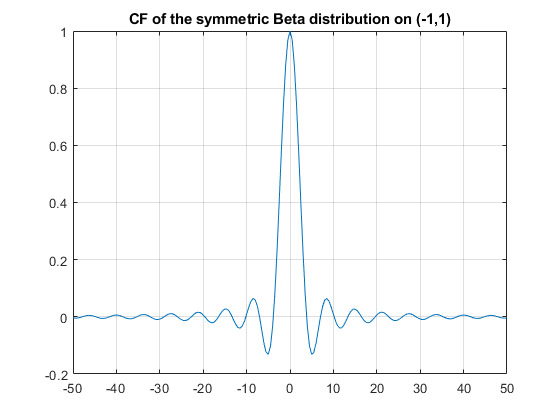

theta = 3/2;
t     = linspace(-50,50,201);
cf    = cf_BetaSymmetric(t,theta);
figure; plot(t,cf); grid
title('CF of the symmetric Beta distribution on (-1,1)')

**Example 2:*** Plot the characteristic function of a linear combination of independent random variables with symmetric beta distribution on the interval *$(-1,1)$*.*

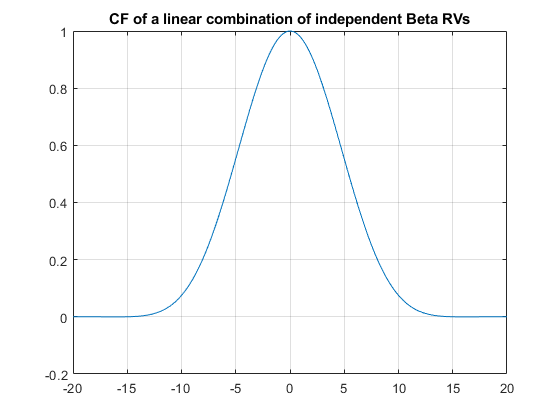

t     = linspace(-20,20,201);
theta = [3 3 4 4 5]/2;
coef  = [1 2 3 4 5]/15;
cf = cf_BetaSymmetric(t,theta,coef);
figure; plot(t,cf),grid
title('CF of a linear combination of independent Beta RVs')

**Example 3:*** Calculate and plot the PDF and CDF of a linear combination of independent random variables with symmetric beta distributions on the interval *$(-1,1)$* by using the inversion algorithm *`cf2DistGP`*.The structure *`result`* containts all the calculated information.*

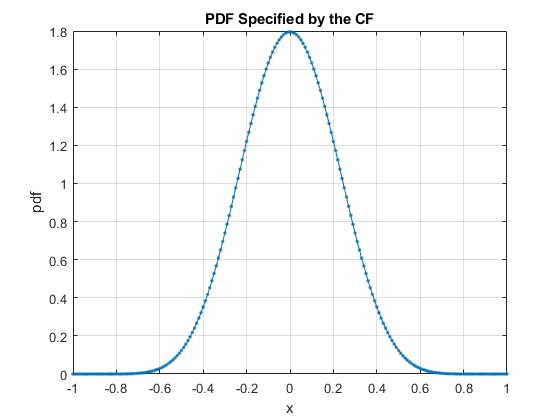

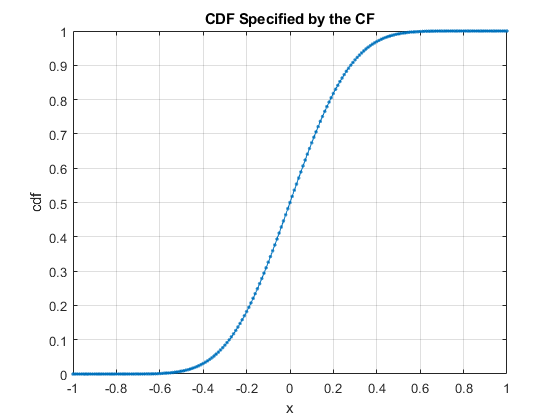

result = struct with fields:
            Description: 'CDF/PDF/QF from the characteristic function CF'
                      x: [1×201 double]
                    cdf: [1×201 double]
                    pdf: [1×201 double]
                   prob: [0.9000 0.9500 0.9900]
                     qf: [0.2797 0.3549 0.4870]
                     cf: @(t)cf_BetaSymmetric(t,theta,coef)
             isCompound: 0
             isCircular: 0
               isInterp: 0
           SixSigmaRule: 6
                      N: 4096
                     dt: 3.1416
                      T: 1.2868e+04
          PrecisionCrit: 3.4503e-36
        myPrecisionCrit: 1.0000e-12
          isPrecisionOK: 1
                  xMean: 0
                   xStd: 0.2152
                   xMin: -1
                   xMax: 1
                cfLimit: 0
              cdfAdjust: 0
    nNewtonRaphsonLoops: 8
           qfCorrection: [3×1 double]
                options: [1×1 struct]
                 tictoc: 0.1075


theta = [3 3 4 4 5]/2;
coef  = [1 2 3 4 5]/15;
cf    = @(t) cf_BetaSymmetric(t,theta,coef);
x     = linspace(-1,1,201);
prob  = [0.9 0.95 0.99];
clear options
options.N = 2^12;
options.xMin = -1;
options.xMax = 1;
result = cf2DistGP(cf,x,prob,options);

disp(result)

#### cf_Chi

#### cf_ChiNC

#### cf_ChiSquare

#### cf_Exponential

#### cf_FisherSnedecor

#### cf_FisherSnedecorNC

#### cf_Gamma

#### cf_GeneralizedExponential

#### cf_Gumbel

#### cf_InverseGamma

#### cf_Laplace

#### cf_MaxwellBoltzmann

#### cf_MaxwellBoltzmannNC

#### cf_Nakagami

#### cf_NakagamiNC

#### cf_Normal

#### cf_Rayleigh

#### cf_RayleighNC

#### cf_Rectangular

#### cf_RectangularSymmetric

#### cf_Rice

#### cf_Stable

#### cf_Student

#### cf_TrapezoidalSymmetric

#### cf_TriangularSymmetric

#### cf_TSPSymmetric

#### cf_Weibull

#### cf_WignerSemicircle

### Tools for manuipulating with the characteristic function

CharFunTool consists of a set of algorithms for manipulating and combining the characteristic functions.

## Utility functions